## User Inputs & Identifying Site

%% the following code identifies the site according to longitude and latitude inputs
%% it also takes in other user inputs such as time period, months of interest, seasons

long = -71.56; % input longitude
lat = 40.88; % input latitude
directory = 'C:\Users\Connor Bayne\Downloads'; % input save location file path, for example, '/Users/user_name/Downloads' on Mac, and 'C:\Users\user_name\Downloads' on Windows
overalltimeperiod = [2010 2011 2012]; % chronological years interest Ex. [2005 2006 2007]
monthyear = [2010 2011 2012]; % specific year or years that contains months to be graphed
monthinput = []; % chronological months of interest Ex. [3 4] for March and April
seasons = [1 2]; % seasons of interest. 1 = spring. 2 = summer. 3 = fall. 4 = winter
seasonpref = [2]; % seasons graphed separate (1), together (2), or both (3). Ex. [1] means user wants separate graphs


% this portion of this code generates URLs to download csv files using the Wind Prospector API
% and downloads these files to the users chosen save location 

% for i = 1:length(overalltimeperiod)
%     urli = sprintf('https://developer.nrel.gov/api/wind-toolkit/wind/wtk_download.csv?api_key=DEMO_KEY&wkt=POINT(%f%%20%f)&attributes=wind_speed,power&names=%d&utc=true&email=ben@gmail.com',long,lat,overalltimeperiod(i));
%     web(urli, '-browser');
% end
% 
% pause(60) % adjust this to how long your computer takes to download csv files
% 
% % The following code only serves to extract the site ID
% dirc = dir(directory);
% % Filter out all the folders. The downloaded files are not in existing folders within the user's downloads
% dirc = dirc(find(~cellfun(@isdir,{dirc(:).name})));
% 
% % I contains the index to the biggest number which is the latest file, latest file dowloaded is of interest
% [A,I] = max([dirc(:).datenum]);
% 
% if ~isempty(I)
%     latestfile = dirc(I).name;
% end
% 
% % latestfile = strcat(directory,latestfile)
% [pathstr,name,ext] = fileparts(latestfile);
% 
% file_name = name;
% site_ID = name(1:5); % generates site ID string 
% 
% pause(10)

## Yearly Code

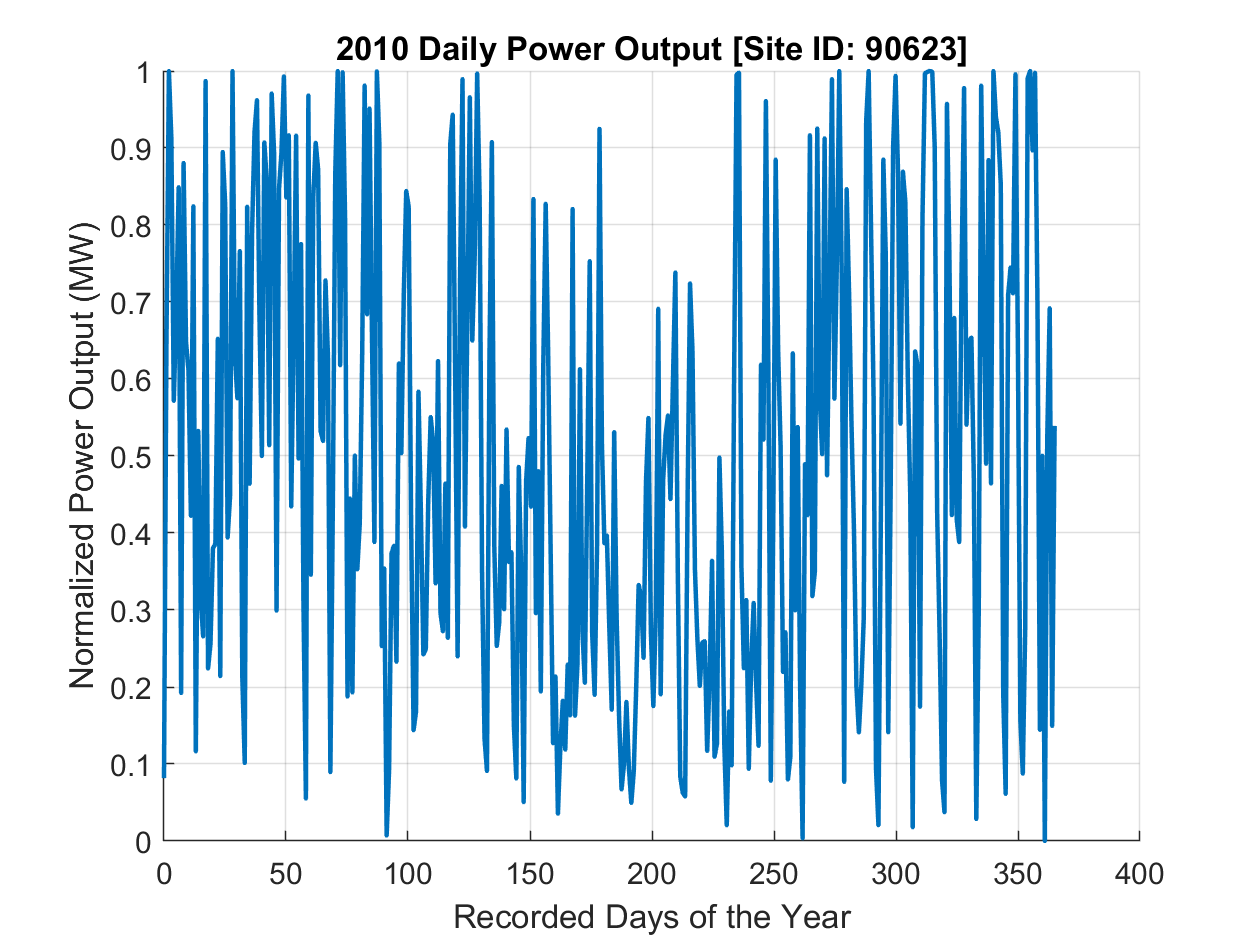

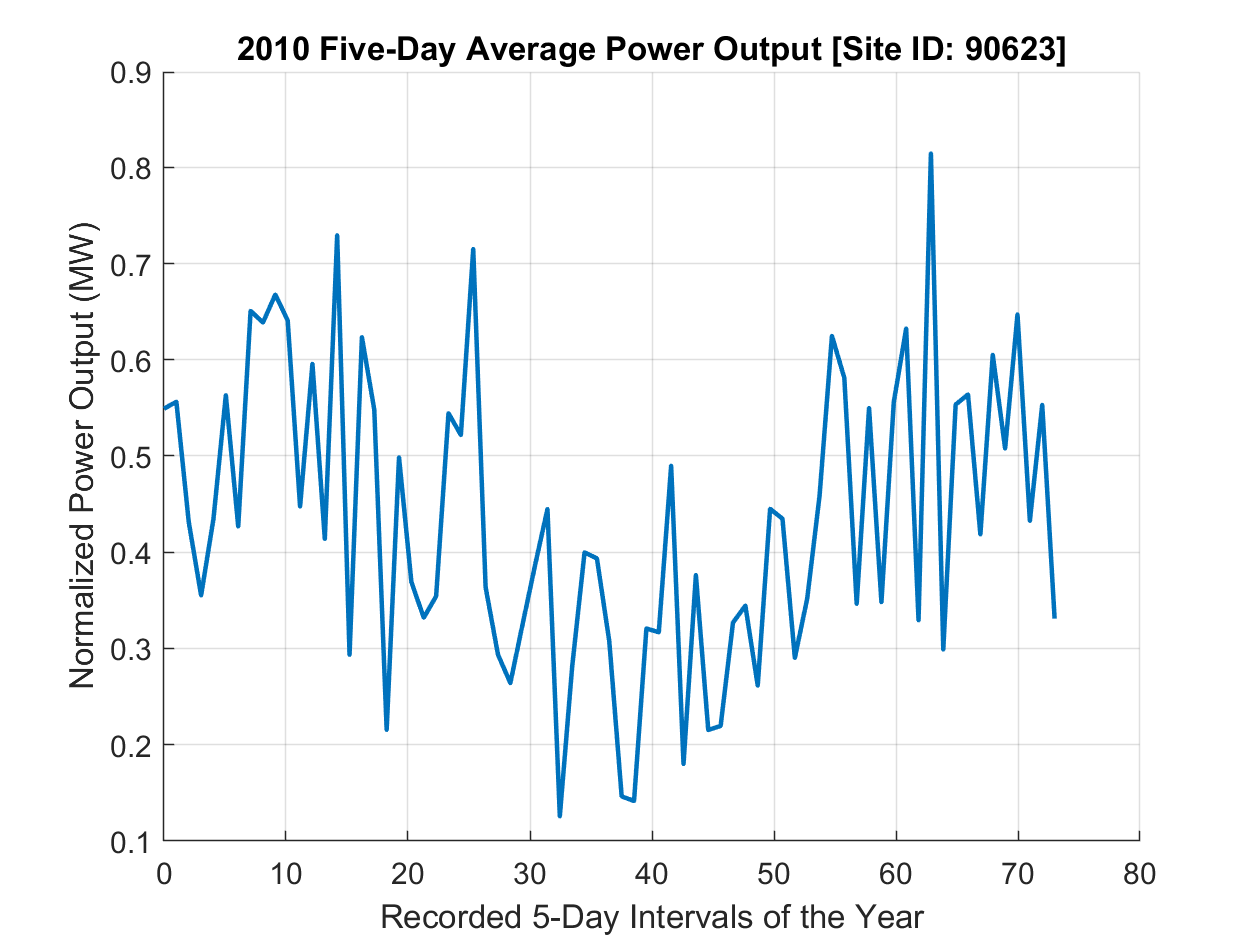

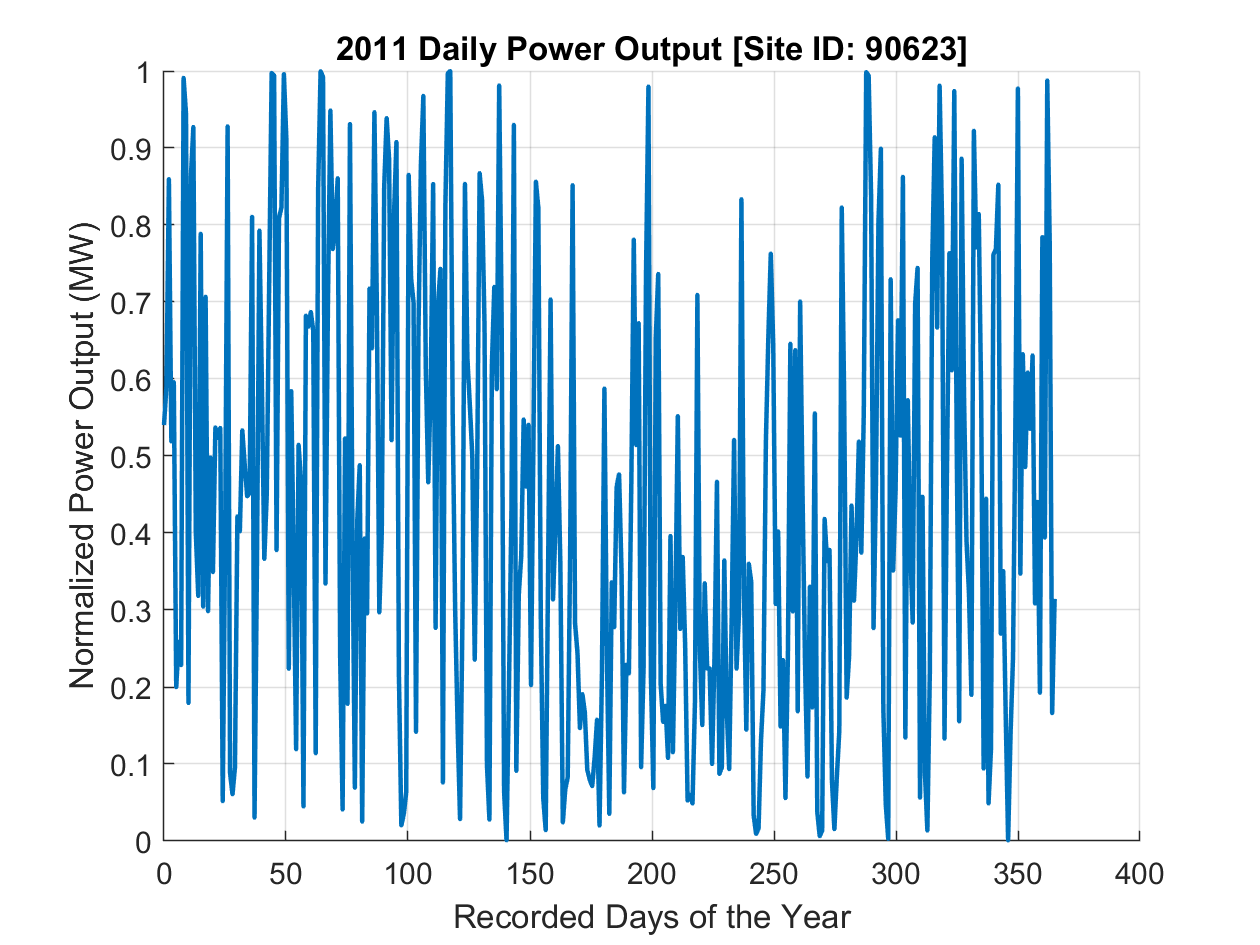

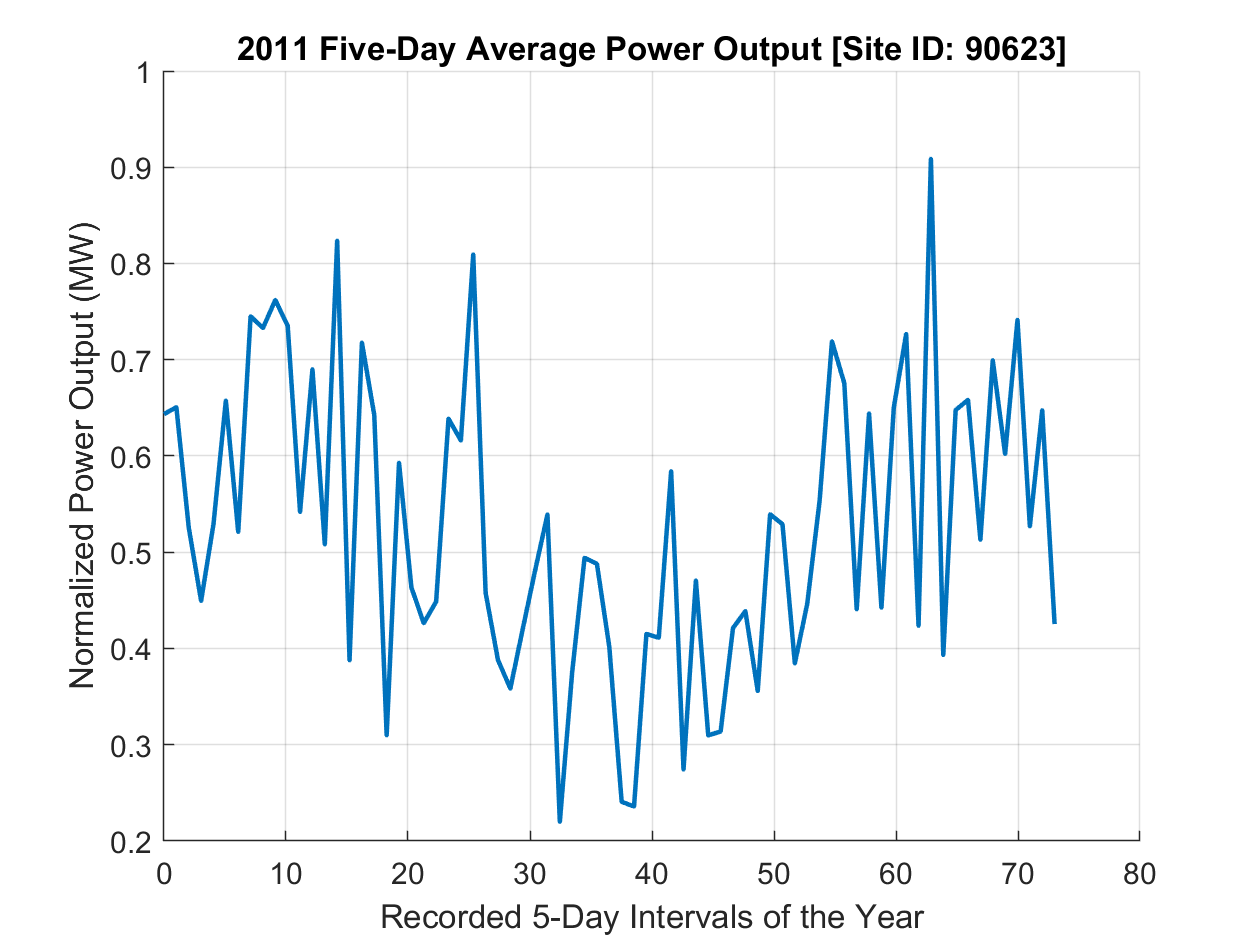

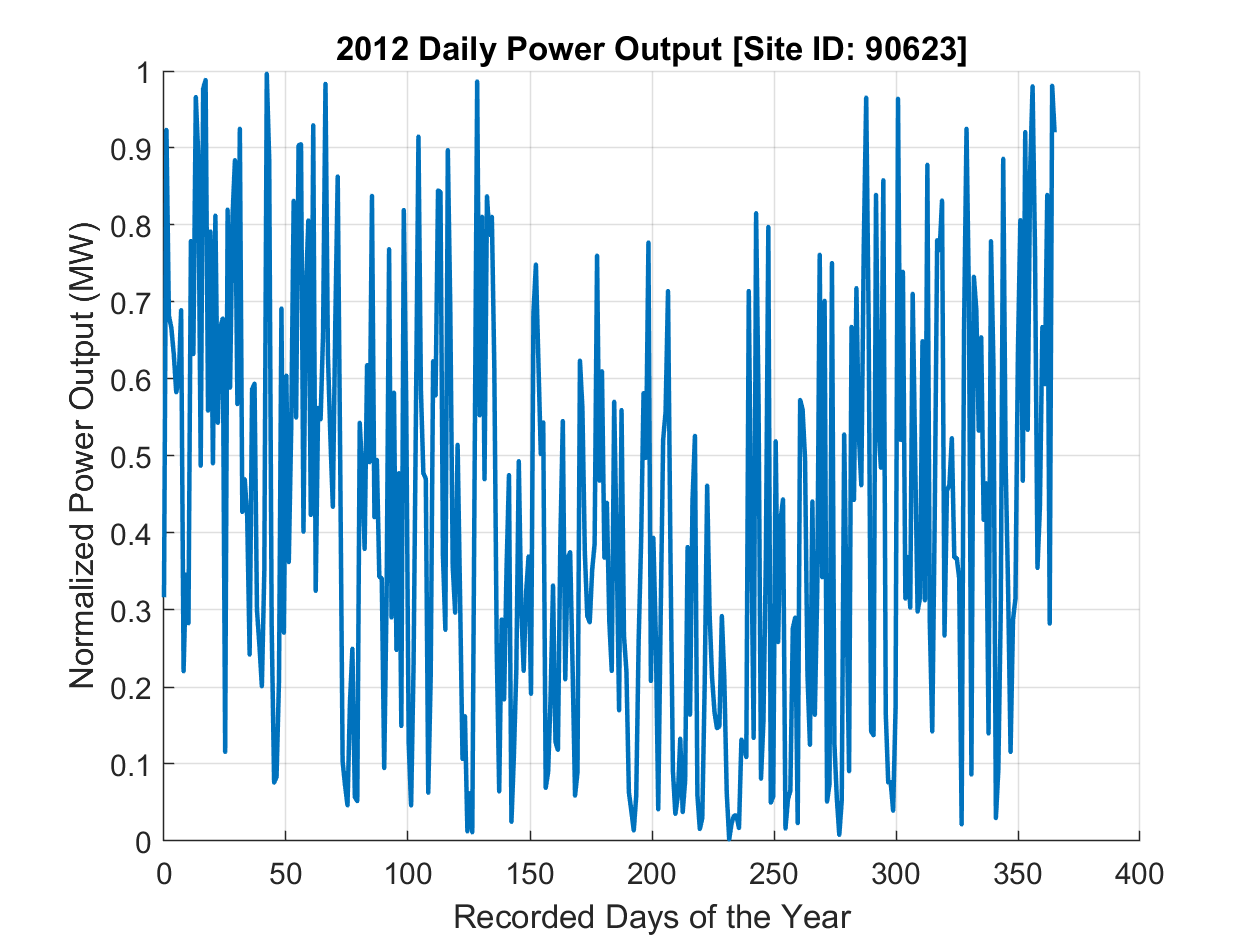

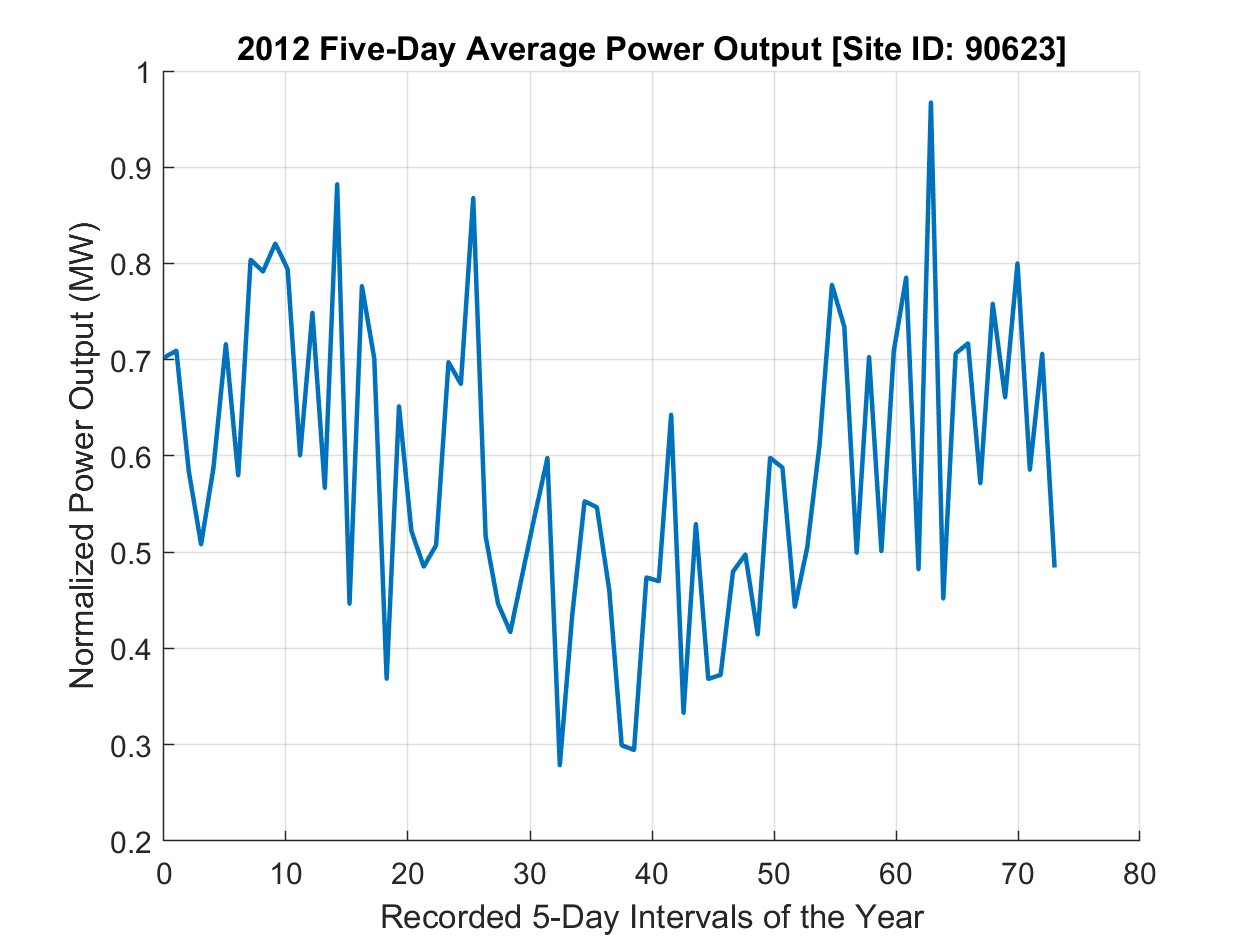

%% the following code graphs the power output over the length of the entire year
%% if multiple years are of interest, it will plot them all seperately and once together

yearlydata = zeros(105120,6,length(overalltimeperiod)); % all data
adjustedyearlydata = zeros(105120,1,length(overalltimeperiod)); % only the yearly power output
dailyyearlydata = zeros(365,length(overalltimeperiod)); % daily average power output over each year
fivedaydata = zeros(73,length(overalltimeperiod)); % every five days, data is averaged
capacity = zeros(length(overalltimeperiod)); % vector containing each year's max capacity

for i = 1:length(overalltimeperiod)
    yearlydata(:,:,i) = sym(yearlydata(:,:,i));
    yearlydata(:,:,i) = readmatrix(sprintf('%s/%s-%d.csv',directory,site_ID,overalltimeperiod(i)),'Range','B4:G105124');
    % normalize yearly data
    capacity(i) = max(yearlydata(:,6,i));
    yearlydata(:,6,i) = yearlydata(:,6,i)/capacity(i);
    % taking only the power output column from overall yearlydata
    adjustedyearlydata(:,1,i) = yearlydata(:,6,i);
end

% each year has 105120 data points which is too many to graph. This code consolidates those points
% into one point for every day. 288 points -> 1 point
for i = 1:length(overalltimeperiod)
    counter = 1;
    for h = 1:288:(length(adjustedyearlydata(:,1,1))-287)
        dailyyearlydata(counter,i) = mean(adjustedyearlydata([h:h+288-1],i)); 
        counter = counter + 1;
    end
end
% averaging yearly data for one data point every five days
for i = 1:length(overalltimeperiod)
    counter = 1;
    for j = 1:5:(365 - 4)
        fivedaydata(counter,i) = mean(dailyyearlydata([j:j+5-1,i]));
        counter = counter + 1;
    end
end

% plotting yearly data, both daily points and 5-day average points
fivedayyeartime = linspace(0,73,73); % intialize time
yeartime = linspace(0,365,365); 

for j = 1:length(overalltimeperiod)
    figure
    hold on
    grid on
    plot(yeartime,dailyyearlydata(:,j),'LineWidth', 1.5)
    title(sprintf('%d Daily Power Output [Site ID: %s]', overalltimeperiod(j), site_ID))
    xlabel('Recorded Days of the Year')
    ylabel('Normalized Power Output (MW)')
    hold off
    %%%
    figure
    hold on
    grid on
    plot(fivedayyeartime,fivedaydata(:,j),'LineWidth',1.5)
    title(sprintf('%d Five-Day Average Power Output [Site ID: %s]', overalltimeperiod(j), site_ID))
    xlabel('Recorded 5-Day Intervals of the Year')
    ylabel('Normalized Power Output (MW)')
    hold off
end

## Monthly Code 

%% the following code filters the overall yearly data into monthly data
%% this monthly data is averaged over each day to generate a plot of the daily average power output
%% only the months of interest are graphed

if isempty(overalltimeperiod) ~= 1 
    % initialize month matrices, making sure months are separated according to length
    January = zeros(288*31,length(monthyear)); March = January; May = January;
    July = January; August = January; October = January; December = January;
    February = zeros(288*28,length(monthyear));
    April = zeros(288*30,length(monthyear)); June = April; September = April; November = April; 
    
    for i = 1:length(overalltimeperiod)   
        % the monthly data will be stored in columns. Each month will be a matrix with columns
        % reflecting different years of that month's data
        
        % January(:,i) corresponds to the january power data from the "i" year in overall monthyear time period
        % find is searching for the first instance of the month column equalling the specified month value
        [janstart(i),~] = find(yearlydata(:,1,i)==1,1); [febstart(i),~] = find(yearlydata(:,1,i)==2,1);
        [marchstart(i),~] = find(yearlydata(:,1,i)==3,1); [aprilstart(i),~] = find(yearlydata(:,1,i)==4,1); 
        [maystart(i),~] = find(yearlydata(:,1,i)==5,1); [junestart(i),~] = find(yearlydata(:,1,i)==6,1);
        [julystart(i),~] = find(yearlydata(:,1,i)==7,1); [augstart(i),~] = find(yearlydata(:,1,i)==8,1);
        [sepstart(i),~] = find(yearlydata(:,1,i)==9,1); [octstart(i),~] = find(yearlydata(:,1,i)==10,1);
        [novstart(i),~] = find(yearlydata(:,1,i)==11,1); [decstart(i),~] = find(yearlydata(:,1,i)==12,1);
        
        % the power output data is located in column 6 of yearlydata
        January(:,i) = squeeze(yearlydata(janstart(i):(febstart(i)-1),6,i)); 
        February(:,i) = squeeze(yearlydata(febstart(i):(marchstart(i)-1),6,i));
        March(:,i) = squeeze(yearlydata(marchstart(i):(aprilstart(i)-1),6,i));
        April(:,i) = squeeze(yearlydata(aprilstart(i):(maystart(i)-1),6,i));
        May(:,i) = squeeze(yearlydata(maystart(i):(junestart(i)-1),6,i)); 
        June(:,i) = squeeze(yearlydata(junestart(i):(julystart(i)-1),6,i));
        July(:,i) = squeeze(yearlydata(julystart(i):(augstart(i)-1),6,i));
        August(:,i) = squeeze(yearlydata(augstart(i):(sepstart(i)-1),6,i));
        September(:,i) = squeeze(yearlydata(sepstart(i):(octstart(i)-1),6,i));
        October(:,i) = squeeze(yearlydata(octstart(i):(novstart(i)-1),6,i));
        November(:,i) = squeeze(yearlydata(novstart(i):(decstart(i)-1),6,i));
        December(:,i) = squeeze(yearlydata(decstart(i):length(yearlydata(:,1,1)),6,i));
        
        % MATLAB cannot graph this many data points, so we must take average values every day
        % which is 288 five minute intervals
        % initialize new month matrices to only contain the average daily power output
        NewJanuary = zeros(31,length(overalltimeperiod)); NewMarch = NewJanuary; NewMay = NewJanuary;
        NewJuly = NewJanuary; NewAugust = NewJanuary; NewOctober = NewJanuary; NewDecember = NewJanuary;
        NewApril = zeros(30,length(overalltimeperiod)); NewJune = NewApril; NewSeptember = NewApril; 
        NewNovember = NewApril; 
        NewFebruary = zeros(28,length(overalltimeperiod));
     
            for g = 1:length(overalltimeperiod)
                counter31 = 1; % set counter to 1
                for k = 1:288:8641
                    % finding the average of every 288 points which is the
                    % number of 5 minute intervals contained in one day
                    NewJanuary(counter31,g) = mean(January([k:k+288-1],g));
                    NewMarch(counter31,g) = mean(March([k:k+288-1],g)); 
                    NewOctober(counter31,g) = mean(October([k:k+288-1],g));
                    NewMay(counter31,g) = mean(May([k:k+288-1],g));
                    NewJuly(counter31,g) = mean(July([k:k+288-1],g));
                    NewAugust(counter31,g) = mean(August([k:k+288-1],g));
                    NewDecember(counter31,g) = mean(December([k:k+288-1],g));
                    counter31 = counter31 + 1;
                end
     
                counter30 = 1; % resetting counter for following months
                for l = 1:288:8353
                    NewApril(counter30,g) = mean(April([l:l+288-1],g));
                    NewJune(counter30,g) = mean(June([l:l+288-1],g));
                    NewNovember(counter30,g) = mean(November([l:l+288-1],g));
                    NewSeptember(counter30,g) = mean(September([l:l+288-1],g));
                    counter30 = counter30 + 1;
                end
                
                counter28 = 1; % reset counter for February
                for k = 1:288:7777
                    NewFebruary(counter28,g) = mean(February([k:k+288-1],g));
                    counter28 = counter28 + 1;
                end
            end
            
        % determining time increments based on length of month 
        jantime = linspace(0,31,31); marchtime = jantime; octtime = jantime; maytime = jantime;
        julytime = jantime; augtime = jantime; dectime = jantime;
        
        apriltime = linspace(0,30,30); junetime = apriltime; novtime = apriltime; septime = apriltime;
        
        febtime = linspace(0,28,28);
        % plotting months of interest
            if ismember(1,monthinput)
                figure
                hold on
                grid on
                plot(jantime,NewJanuary(:,i),'LineWidth', 1.5)
                title(sprintf('January %d Power Output [Site ID: %s]', monthyear(i), site_ID))
                xlabel('Recorded Days of the Month')
                ylabel('Output Power (MW)')
                hold off
            end
            if ismember(2,monthinput)
                figure
                hold on
                grid on
                plot(febtime,NewFebruary(:,i),'LineWidth', 1.5)
                title(sprintf('February %d Power Output [Site ID: %s]', monthyear(i), site_ID))
                xlabel('Recorded Days of the Month')
                ylabel('Output Power (MW)')
                hold off
            end
            if ismember(3,monthinput)
                figure
                hold on
                grid on
                plot(marchtime,NewMarch(:,i),'LineWidth', 1.5)
                title(sprintf('March %d Power Output [Site ID: %s]', monthyear(i), site_ID))
                xlabel('Recorded Days of the Month')
                ylabel('Output Power (MW)')
                hold off
            end
            if ismember(4,monthinput)
                figure
                hold on
                grid on
                plot(apriltime,NewApril(:,i),'LineWidth', 1.5)
                title(sprintf('April %d Power Output [Site ID: %s]', monthyear(i), site_ID))
                xlabel('Recorded Days of the Month')
                ylabel('Output Power (MW)')
                hold off
            end
            if ismember(5,monthinput)
                figure
                hold on
                grid on
                plot(maytime,NewMay(:,i),'LineWidth', 1.5)
                title(sprintf('May %d Power Output [Site ID: %s]', monthyear(i), site_ID))
                xlabel('Recorded Days of the Month')
                ylabel('Output Power (MW)')
                hold off
            end
            if ismember(6,monthinput) 
                figure
                hold on
                grid on
                plot(junetime,NewJune(:,i),'LineWidth', 1.5)
                title(sprintf('June %d Power Output [Site ID: %s]', monthyear(i), site_ID))
                xlabel('Recorded Days of the Month')
                ylabel('Output Power (MW)')
                hold off
            end
            if ismember(7,monthinput) 
                figure
                hold on
                grid on
                plot(julytime,NewJuly(:,i),'LineWidth', 1.5)
                title(sprintf('July %d Power Output [Site ID: %s]', monthyear(i), site_ID))
                xlabel('Recorded Days of the Month')
                ylabel('Output Power (MW)')
                hold off
            end
            if ismember(8,monthinput) 
                figure
                hold on
                grid on
                plot(augtime,NewAugust(:,i),'LineWidth', 1.5)
                title(sprintf('August %d Power Output [Site ID: %s]', monthyear(i), site_ID))
                xlabel('Recorded Days of the Month')
                ylabel('Output Power (MW)')
                hold off
            end
            if ismember(9,monthinput) 
                figure
                hold on
                grid on 
                plot(septime,NewSeptember(:,i),'LineWidth', 1.5)
                title(sprintf('September %d Power Output [Site ID: %s]', monthyear(i), site_ID))
                xlabel('Recorded Days of the Month')
                ylabel('Output Power (MW)')
                hold off
            end
            if ismember(10,monthinput) 
                figure
                hold on
                grid on
                plot(octtime,NewOctober(:,i),'LineWidth', 1.5)
                title(sprintf('October %d Power Output [Site ID: %s]', monthyear(i), site_ID))
                xlabel('Recorded Days of the Month')
                ylabel('Output Power (MW)')
                hold off
            end
            if ismember(11,monthinput) 
                figure
                hold on
                grid on
                plot(novtime,NewNovember(:,i),'LineWidth', 1.5)
                title(sprintf('November %d Power Output [Site ID: %s]', monthyear(i), site_ID))
                xlabel('Recorded Days of the Month')
                ylabel('Output Power (MW)')
                hold off
            end
            if ismember(12,monthinput)
                figure
                hold on
                grid on
                plot(dectime,NewDecember(:,i),'LineWidth', 1.5)
                title(sprintf('December %d Power Output [Site ID: %s]', monthyear(i), site_ID))
                xlabel('Recorded Days of the Month')
                ylabel('Output Power (MW)')
                hold off
            end    
    end % end of length(monthyear) for loop    
end % end of isempty(monthinput) for loop  

## Seasonal Code

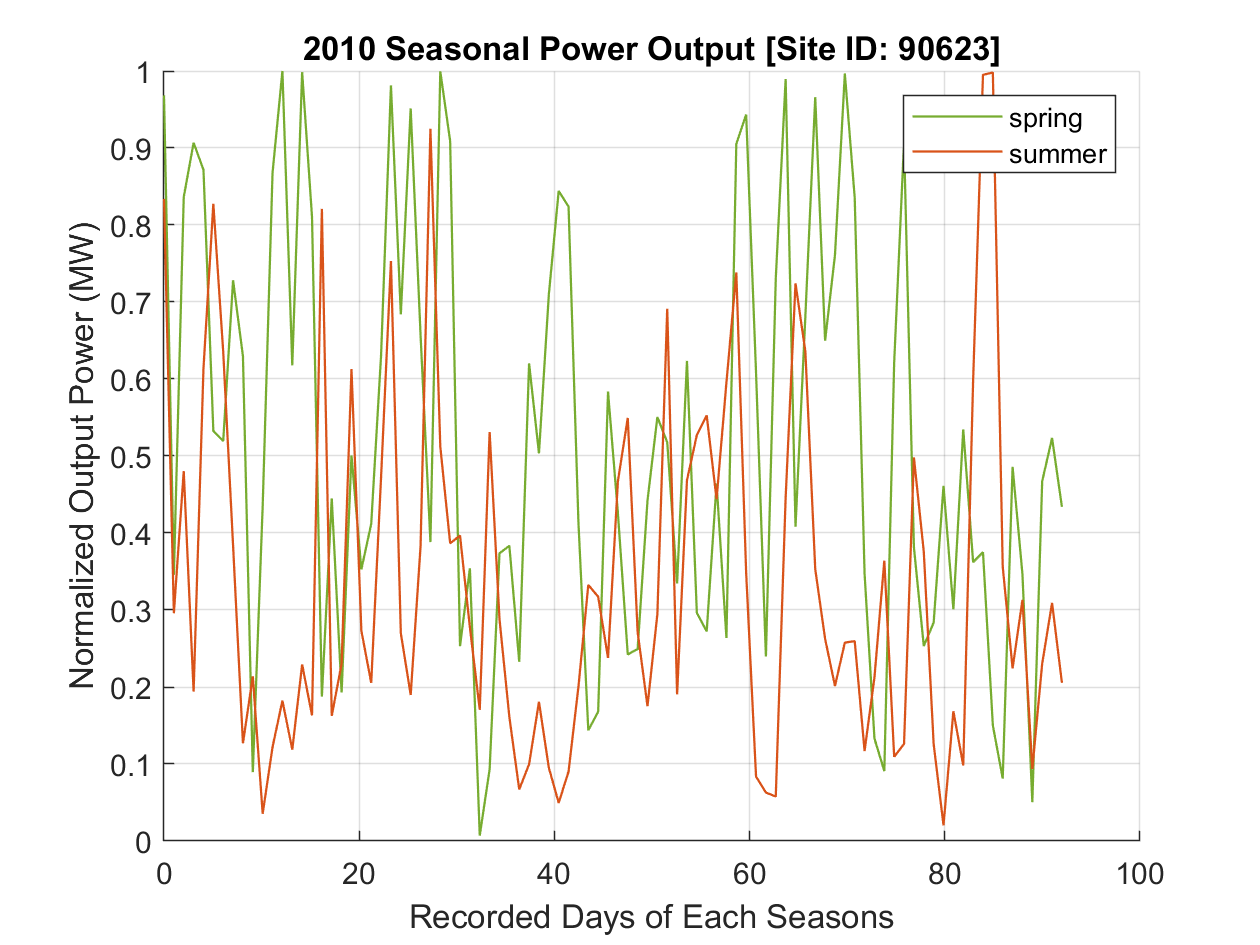

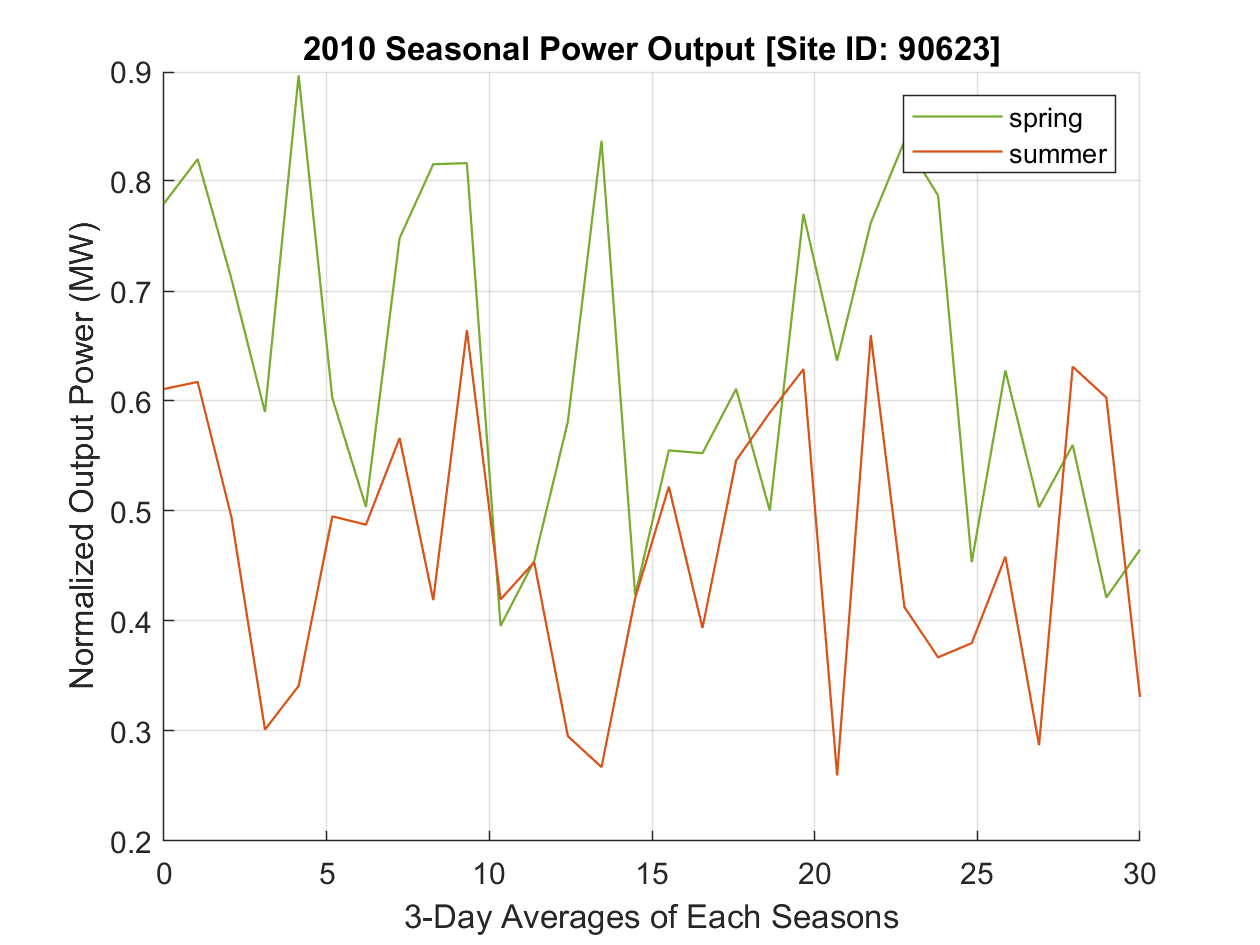

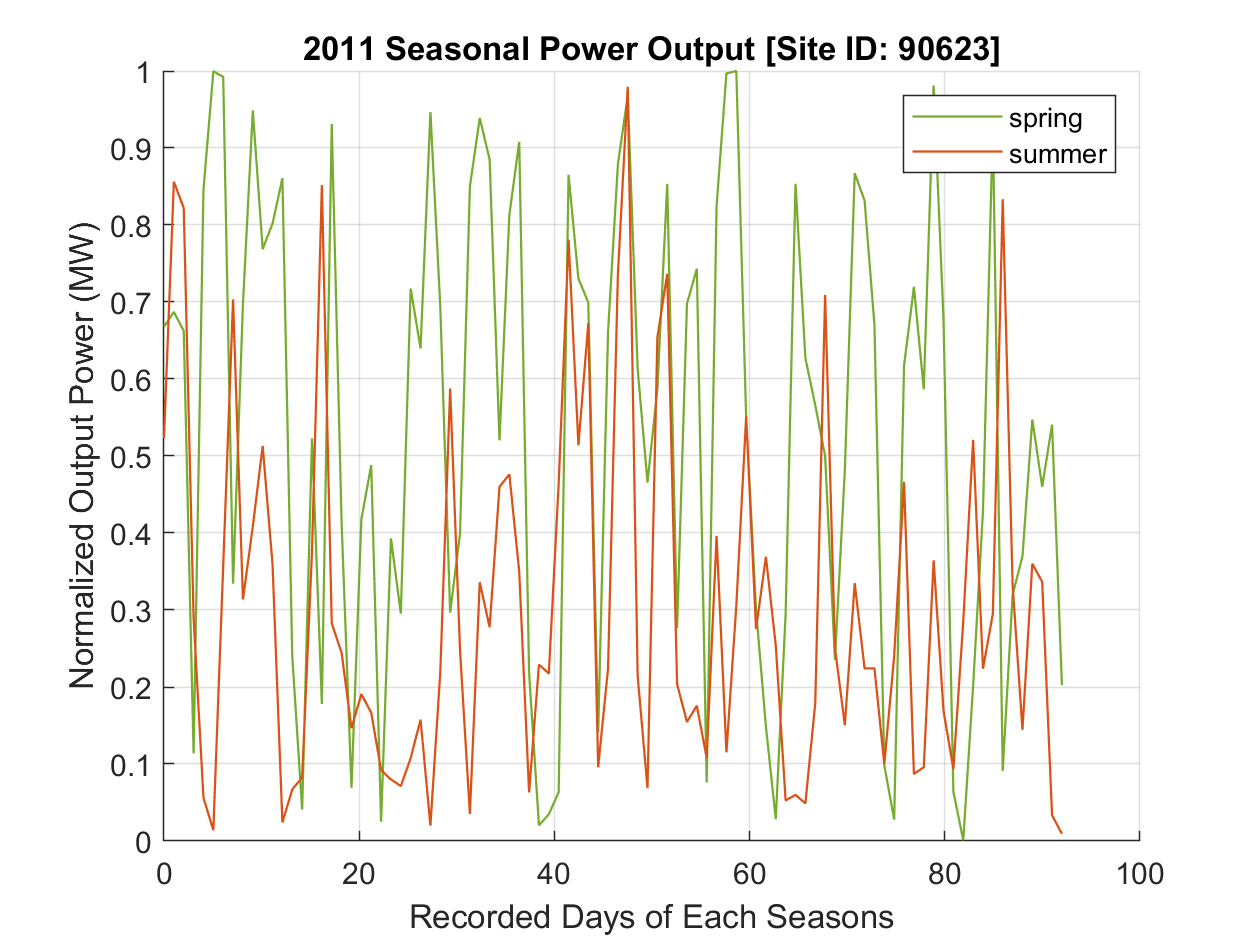

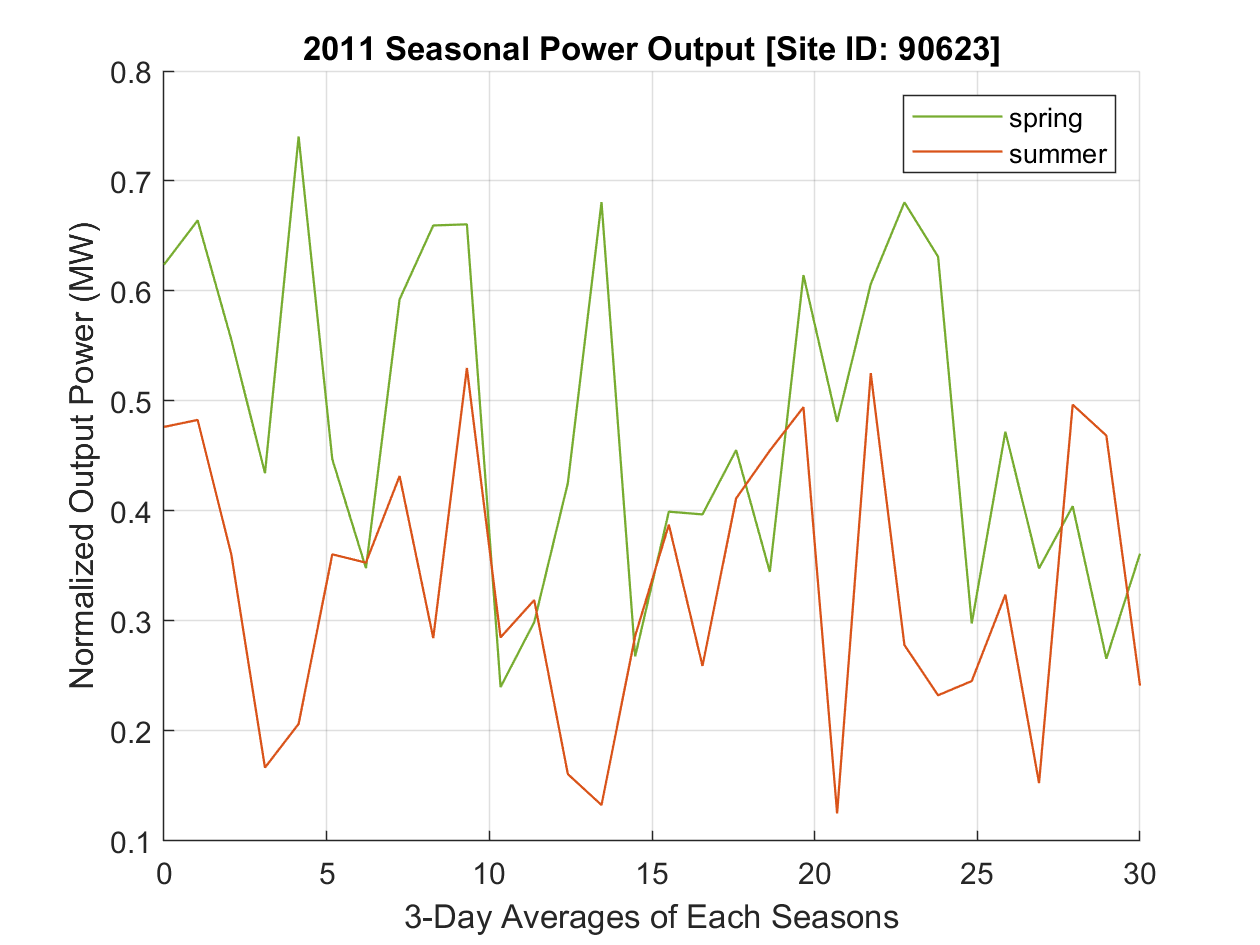

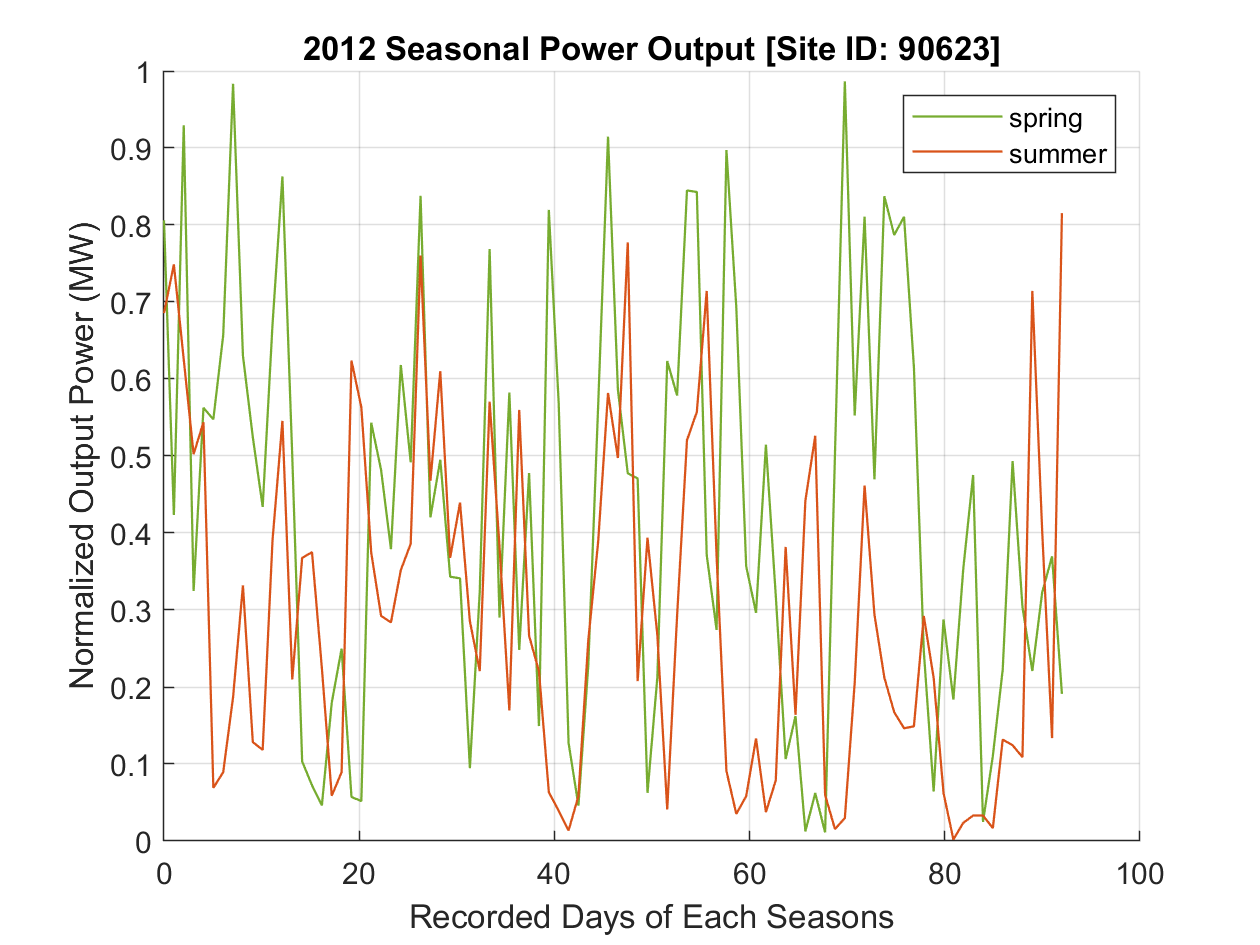

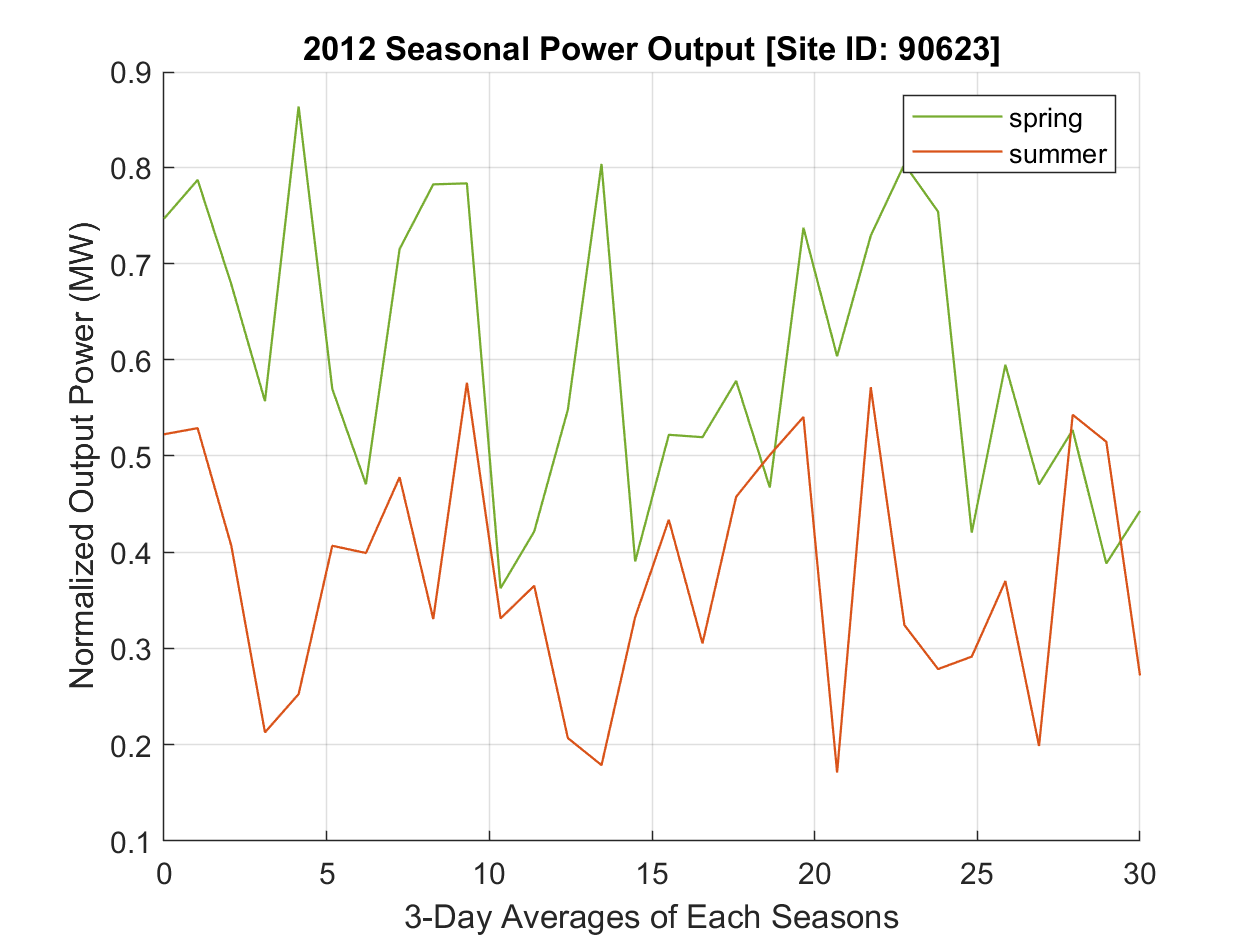

%% the following code combines monthly data into seasonal data and graphs the seasons
%% the user can choose whether to graph seasons together or seperately

% fall: September, October & Novemeber
% winter: December, January & February
% spring: March, April & May
% summer: June, July & August

% initialize seasonal matrices with number of days as rows and years as columns
spring = zeros(92,length(overalltimeperiod));
summer = zeros(92,length(overalltimeperiod));
fall = zeros(91,length(overalltimeperiod));
winter = zeros(90,length(overalltimeperiod));

avgspring = zeros(30,length(overalltimeperiod));
avgsummer = zeros(30,length(overalltimeperiod));
avgfall = zeros(30,length(overalltimeperiod));
avgwinter = zeros(30,length(overalltimeperiod));

% filling seasonal matrices with yearly seasonal data
for k = 1:length(overalltimeperiod)
    fall(1:30,k) = NewSeptember(:,k); 
    fall(31:61,k) = NewOctober(:,k); 
    fall(62:91,k) = NewNovember(:,k);
    winter(1:31,k) = NewDecember(:,k);
    winter(32:62,k) = NewJanuary(:,k);
    winter(63:90,k) = NewFebruary(:,k);
    spring(1:31,k) = NewMarch(:,k); 
    spring(32:61,k) = NewApril(:,k);
    spring(62:92,k) = NewMay(:,k);
    summer(1:30,k) = NewJune(:,k);
    summer(31:61,k) = NewJuly(:,k);
    summer(62:92,k) = NewAugust(:,k);
end

% creating seasonal time periods
falltime = linspace(0,91,91);
wintertime = linspace(0,90,90);
springtime = linspace(0,92,92);
summertime = linspace(0,92,92);

avgseasontime = linspace(0,30,30);

% consolidating seasonal data into 3 day averages, with the last data point
% in spring and summer being the average of days 88-92 and the last data
% point in fall being the average of days 88-91
for j = 1:length(overalltimeperiod)
    counter = 1;
    for k = 1:3:88
        if k <= 85
            avgspring(counter,j) = mean(spring([k:k+3-1,j]));
            avgsummer(counter,j) = mean(summer([k:k+3-1,j]));
            avgfall(counter,j) = mean(fall([k:k+3-1,j]));
            avgwinter(counter,j) = mean(winter([k:k+3-1,j]));
        end
        if k > 85
            avgspring(30,j) = mean(spring([88:92,j]));
            avgsummer(30,j) = mean(summer([88:92,j]));
            avgfall(30,j) = mean(fall([88:91,j]));
            avgwinter(30,j) = mean(winter([88:90,j]));
        end
        counter = counter + 1;
    end
end

% plotting only seasons of interest, taking into account graphing preferences
% spring
if ismember(1,seasons) && ismember(1,seasonpref) || ismember(3,seasonpref) && ismember(1,seasons)
    for k = 1:length(overalltimeperiod)
        figure
        hold on
        grid on
        plot(springtime,spring(:,k),'LineWidth', 1.5,'Color','[0.4660 0.6740 0.1880]')
        title(sprintf('Spring %d Power Output [Site ID: %s]', overalltimeperiod(k), site_ID))
        xlabel('Recorded Days of the Season')
        ylabel('Output Power (MW)')
        hold off
        
        figure
        hold on
        grid on
        plot(avgseasontime,avgspring(:,k),'LineWidth', 1.5,'Color','[0.4660 0.6740 0.1880]')
        title(sprintf('3-Day Average Spring %d Power Output [Site ID: %s]', overalltimeperiod(k), site_ID))
        xlabel('3-Day Intervals of the Season')
        ylabel('Normalized Output Power (MW)')
        hold off
    end
end
% summer
if ismember(2,seasons) && ismember(1,seasonpref) || ismember(3,seasonpref) && ismember(2,seasons)
    for k = 1:length(overalltimeperiod)
        figure
        hold on
        grid on
        plot(summertime,summer(:,k),'LineWidth', 1.5,'Color','[0.8500 0.3250 0.0980]')
        title(sprintf('Summer %d Power Output [Site ID: %s]', overalltimeperiod(k), site_ID))
        xlabel('Recorded Days of the Season')
        ylabel('Output Power (MW)')
        hold off
        
        figure
        hold on
        grid on
        plot(avgseasontime,avgsummer(:,k),'LineWidth', 1.5,'Color','[0.8500 0.3250 0.0980]')
        title(sprintf('3-Day Average Summer %d Power Output [Site ID: %s]', overalltimeperiod(k), site_ID))
        xlabel('3-Day Intervals of the Season')
        ylabel('Normalized Output Power (MW)')
        hold off
    end
end
% fall
if ismember(3,seasons) && ismember(1,seasonpref) || ismember(3,seasonpref) && ismember(3,seasons)
    for k = 1:length(overalltimeperiod)
        figure
        hold on
        grid on
        plot(falltime,fall(:,k),'LineWidth', 1.5,'Color','[0.9290 0.6940 0.1250]')
        title(sprintf('Fall %d Power Output [Site ID: %s]', overalltimeperiod(k), site_ID))
        xlabel('Recorded Days of the Season')
        ylabel('Output Power (MW)')
        hold off
        
        figure
        hold on
        grid on
        plot(avgseasontime,avgfall(:,k),'LineWidth', 1.5,'Color','[0.9290 0.6940 0.1250]')
        title(sprintf('3-Day Average Fall %d Power Output [Site ID: %s]', overalltimeperiod(k), site_ID))
        xlabel('3-Day Intervals of the Season')
        ylabel('Normalized Output Power (MW)')
        hold off
    end
end
% winter
if ismember(4,seasons) && ismember(1,seasonpref) || ismember(3,seasonpref) && ismember(4,seasons)
    for k = 1:length(overalltimeperiod)
        figure
        hold on
        grid on
        plot(wintertime,winter(:,k),'LineWidth', 1.5,'Color','[0.3010 0.7450 0.9330]')
        title(sprintf('Winter %d Power Output [Site ID: %s]', overalltimeperiod(k), site_ID))
        xlabel('Recorded Days of the Season')
        ylabel('Output Power (MW)')
        hold off
        
        figure
        hold on
        grid on
        plot(avgseasontime,avgwinter(:,k),'LineWidth', 1.5,'Color','[0.3010 0.7450 0.9330]')
        title(sprintf('3-Day Average Winter %d Power Output [Site ID: %s]', overalltimeperiod(k), site_ID))
        xlabel('3-Day Intervals of the Season')
        ylabel('Normalized Output Power (MW)')
        hold off
    end
end

% if user desires seasons graphed on the same figure, whether the user
% chose both or together as their seasonal preference
if ismember(2,seasonpref) || ismember(3,seasonpref)
    for k = 1:length(overalltimeperiod)
        figure
        hold on
        grid on
        if ismember(1,seasons)
            plot(springtime,spring(:,k),'LineWidth',0.75,'Color','[0.4660 0.6740 0.1880]')
        end
        if ismember(2,seasons)
            plot(summertime,summer(:,k),'LineWidth',0.75,'Color','[0.8500 0.3250 0.0980]')
        end
        if ismember(3,seasons)
            plot(falltime,fall(:,k),'LineWidth',0.75,'Color','[0.9290 0.6940 0.1250]')
        end
        if ismember(4,seasons)
            plot(wintertime,winter(:,k),'LineWidth',0.75,'Color','[0.3010 0.7450 0.9330]')
        end
        % determining legend
        if length(seasons) == 2
            if ismember(1,seasons) && ismember (2,seasons)
                legend('spring','summer')
            elseif ismember(1,seasons) && ismember(3,seasons)
                legend('spring','fall')
            elseif ismember(1,seasons) && ismember(4,seasons)
                legend('spring','winter')
            elseif ismember(2,seasons) && ismember(3,seasons)
                legend('summer','fall')
            elseif ismember(2,seasons) && ismember(4,seasons)
                legend('summer','winter')
            elseif ismember(3,seasons) && ismember(4,seasons)
                legend('fall','winter')
            end
        elseif length(seasons) == 3
            if ismember(1,seasons) && ismember(2,seasons) && ismember(3,seasons)
                legend('spring','summer','fall')
            elseif ismember(1,seasons) && ismember(2,seasons) && ismember(4,seasons)
                legend('spring','summer','winter')
            elseif ismember(1,seasons) && ismember(3,seasons) && ismember(4,seasons)
                legend('spring','fall','winter')
            elseif ismember(2,seasons) && ismember(3,seasons) && ismember(4,seasons)
                legend('summer','fall','winter')
            end
        elseif length(seasons) == 4
            legend('spring','summer','fall','winter')
        end
        title(sprintf('%d Seasonal Power Output [Site ID: %s]', overalltimeperiod(k), site_ID))
        xlabel('Recorded Days of Each Seasons')
        ylabel('Normalized Output Power (MW)')
        hold off
        
        % plotting 3-day average month data
        figure
        hold on
        grid on
        if ismember(1,seasons)
            plot(avgseasontime,avgspring(:,k),'LineWidth',0.75,'Color','[0.4660 0.6740 0.1880]')
        end
        if ismember(2,seasons)
            plot(avgseasontime,avgsummer(:,k),'LineWidth',0.75,'Color','[0.8500 0.3250 0.0980]')
        end
        if ismember(3,seasons)
            plot(avgseasontime,avgfall(:,k),'LineWidth',0.75,'Color','[0.9290 0.6940 0.1250]')
        end
        if ismember(4,seasons)
            plot(avgseasontime,avgwinter(:,k),'LineWidth',0.75,'Color','[0.3010 0.7450 0.9330]')
        end
        % determining legend
        if length(seasons) == 2
            if ismember(1,seasons) && ismember (2,seasons)
                legend('spring','summer')
            elseif ismember(1,seasons) && ismember(3,seasons)
                legend('spring','fall')
            elseif ismember(1,seasons) && ismember(4,seasons)
                legend('spring','winter')
            elseif ismember(2,seasons) && ismember(3,seasons)
                legend('summer','fall')
            elseif ismember(2,seasons) && ismember(4,seasons)
                legend('summer','winter')
            elseif ismember(3,seasons) && ismember(4,seasons)
                legend('fall','winter')
            end
        elseif length(seasons) == 3
            if ismember(1,seasons) && ismember(2,seasons) && ismember(3,seasons)
                legend('spring','summer','fall')
            elseif ismember(1,seasons) && ismember(2,seasons) && ismember(4,seasons)
                legend('spring','summer','winter')
            elseif ismember(1,seasons) && ismember(3,seasons) && ismember(4,seasons)
                legend('spring','fall','winter')
            elseif ismember(2,seasons) && ismember(3,seasons) && ismember(4,seasons)
                legend('summer','fall','winter')
            end
        elseif length(seasons) == 4
            legend('spring','summer','fall','winter')
        end
        title(sprintf('%d Seasonal Power Output [Site ID: %s]', overalltimeperiod(k), site_ID))
        xlabel('3-Day Averages of Each Seasons')
        ylabel('Normalized Output Power (MW)')
        hold off
    end
end